# **Generalized chi-square distribution** · Getting started

The generalized chi-square variable is a quadratic form of a normal variable, or equivalently, a linear sum of independent non-central chi-square variables and a normal variable.

For function features and documentation, type:

doc gx2_to_norm_quad_params
doc norm_quad_to_gx2_params
doc gx2stat
doc gx2rnd
doc gx2char
doc gx2cdf
doc gx2pdf
doc gx2inv

Abhranil Das

Center for Perceptual Systems, University of Texas at Austin

Comments, questions, bugs to abhranil.das@utexas.edu

If you use this toolbox, please cite:

- [Methods to integrate multinormals and compute classification measures](https://arxiv.org/abs/2012.14331).

- [New methods to compute the generalized chi-square distribution.](https://arxiv.org/abs/2404.05062)

## Calculate mean and variance

% gx2 parameters
w=[1 -10 2];
k=[1 2 3];
lambda=[2 3 7];
s=5;
m=10;

[mu,v]=gx2stat(w,k,lambda,s,m)

mu = -17

v = 1771

## Generate random samples

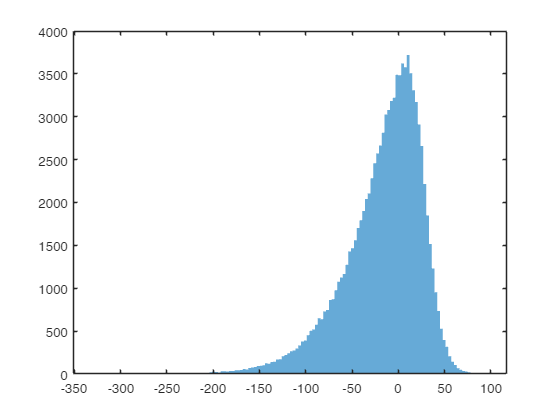

r=gx2rnd(w,k,lambda,s,m,[1 1e5]);
figure;
histogram(r,'EdgeColor','none')

## Compute PDF, CDF and inverse CDF with default methods

x=[10 25];
f=gx2pdf(x,w,k,lambda,s,m)

f =     0.0121    0.0088


p=gx2cdf(x,w,k,lambda,s,m)

p =     0.7150    0.8790


% find the median by using the inverse CDF function:
x_med=gx2inv(.5,w,k,lambda,s,m)

x_med = -8.7657

% Compute quantiles for cdf values of 1e-3 and 1e-2, by supplying their log10 values:
x_q=gx2inv([-3 -2],w,k,lambda,s,m)

x_q =  -219.2553 -149.2618


% verify that cdf values here are indeed 1e-3 and 1e-2
p=gx2cdf(x_q,w,k,lambda,s,m)

p =     0.0010    0.0100


% Compute quantiles for complementary cdf values of 1e-3 and 1e-2, by supplying their log10 values:
x_q=gx2inv([-3 -2],w,k,lambda,s,m,'upper')

x_q =    69.4899   51.0338


% verify that ccdf values here are indeed 1e-3 and 1e-2
p=gx2cdf(x_q,w,k,lambda,s,m,'upper')

p =     0.0010    0.0100


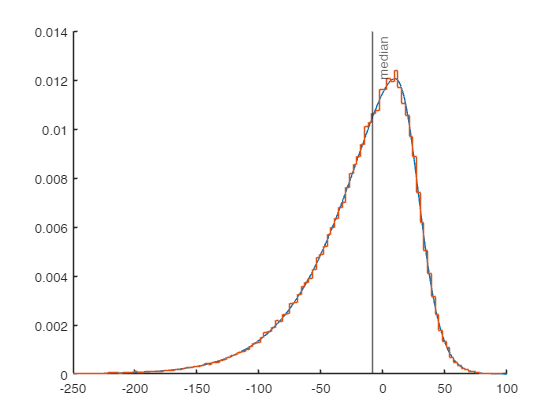

% compute the PDF over most of the span of the distribution.
% with the 'full' argument, the span x is computed automatically.
[f,~,x]=gx2pdf('full',w,k,lambda,s,m);

% now compare the sampled histogram with the computed PDF
figure; hold on
plot(x,f)
histogram(r,'normalization','pdf','displaystyle','stairs')
xline(x_med,'-',{'median'},'labelorientation','aligned') % mark the computed median
xlim([-250 100])

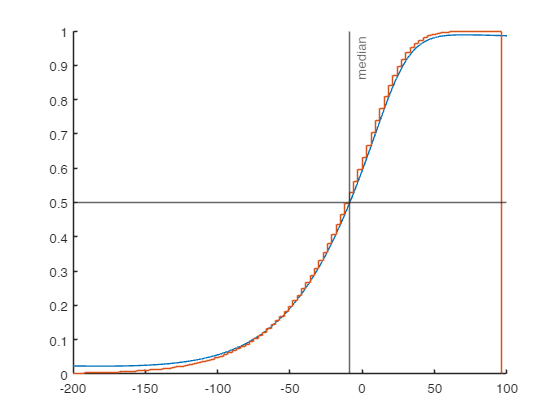

% compute CDF over most of the span of the distribution.
% the 'full' argument uses the IFFT method, good for quick rough plots,
% but less accurate (esp. for CDF) than some other methods
[p,~,x]=gx2cdf('full',w,k,lambda,s,m);

% now compare the sampled histogram with the computed CDF
figure; hold on
plot(x,p)
histogram(r,'normalization','cdf','displaystyle','stairs')
% mark the computed median, and verify that it sits at 0.5 on the vertical axis:
xline(x_med,'-',{'median'},'labelorientation','aligned')
yline(0.5)
xlim([-200 100])

## Compute CDF, PDF and inverse CDF with each exact method and its settings

### A non-elliptic distribution

w=[-2 -5 2];
k=[2 1 3];
lambda=[0 4 4];
s=3;
m=-20;

% first find the quantile points at 0.1% in each tail
x_bounds=gx2inv([0.001 0.999],w,k,lambda,s,m)

x_bounds =  -142.8108   24.8079


% now compute within this range
x=linspace(x_bounds(1),x_bounds(2),50);

% compute CDF
p_ifft=gx2cdf(x,w,k,lambda,s,m,'method','ifft');
p_imhof=gx2cdf(x,w,k,lambda,s,m,'method','imhof');
p_ray=gx2cdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e4);

Using GPU. To use only CPU, set gpu_batch to 0.


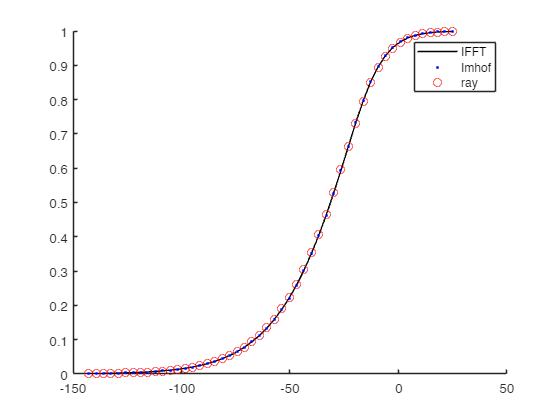

figure; hold on
plot(x,p_ifft,'-k')
plot(x,p_imhof,'.b')
plot(x,p_ray,'or')
legend('IFFT','Imhof','ray')

% compute PDF
f_ifft=gx2pdf(x,w,k,lambda,s,m,'method','ifft');
f_imhof=gx2pdf(x,w,k,lambda,s,m,'method','imhof');
f_ray=gx2pdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e6);

Using GPU. To use only CPU, set gpu_batch to 0.


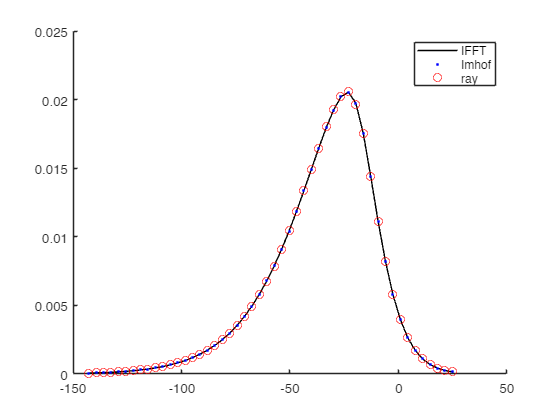


figure; hold on
plot(x,f_ifft,'-k')
plot(x,f_imhof,'.b')
plot(x,f_ray,'or')
legend('IFFT','Imhof','ray')

% Compute quantiles for tiny cdf values of 1e-1000 and 1e-2000, by supplying
% their log10 values. Use a forward cdf method that can get down to such tiny values.
% Here we use the infinite-tail approximation.
x_q=gx2inv([-1e3 -2e3],w,k,lambda,s,m,'method','tail')

x_q = 1.0e+04 *

   -2.4365   -4.7950


% now verify using an exact cdf method that cdf values here are indeed 1e-1000 and 1e-2000:
p=gx2cdf(x_q,w,k,lambda,s,m,'method','ray','n_rays',1e7)

Using GPU. To use only CPU, set gpu_batch to 0.


p = 1.0e+03 *

   -1.0067   -2.0159


% now do the same for the upper tail:
x_q=gx2inv([-1e3 -2e3],w,k,lambda,s,m,'upper','method','tail')

x_q = 1.0e+04 *

    0.9724    1.9159


p=gx2cdf(x_q,w,k,lambda,s,m,'upper','method','ray','n_rays',1e7)

Using GPU. To use only CPU, set gpu_batch to 0.


p = 1.0e+03 *

   -1.0017   -2.0052


### An elliptic distribution

Here we can use Ruben's method too.

w=[3 4 5];
k=[1 2 3];
lambda=[2 3 7];
s=0;
m=-100;

% first find the quantile points at 0.1% in each tail
x_bounds=gx2inv([0.001 0.999],w,k,lambda,s,m)

x_bounds =   -90.5258  122.3200


% now compute within this range
x=linspace(x_bounds(1),x_bounds(2),50);

% compute CDF
p_ifft=gx2cdf(x,w,k,lambda,s,m,'method','ifft');
p_imhof=gx2cdf(x,w,k,lambda,s,m,'method','imhof');
p_ray=gx2cdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e4);

Using GPU. To use only CPU, set gpu_batch to 0.


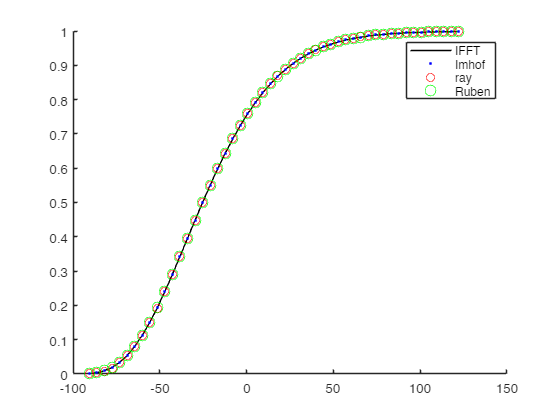

p_ruben=gx2cdf(x,w,k,lambda,s,m,'method','ruben');

figure; hold on
plot(x,p_ifft,'-k')
plot(x,p_imhof,'.b')
plot(x,p_ray,'or')
plot(x,p_ruben,'og','MarkerSize',8)
legend('IFFT','Imhof','ray', 'Ruben')

% compute PDF
f_ifft=gx2pdf(x,w,k,lambda,s,m,'method','ifft');
f_imhof=gx2pdf(x,w,k,lambda,s,m,'method','imhof');
f_ray=gx2pdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e6);

Using GPU. To use only CPU, set gpu_batch to 0.


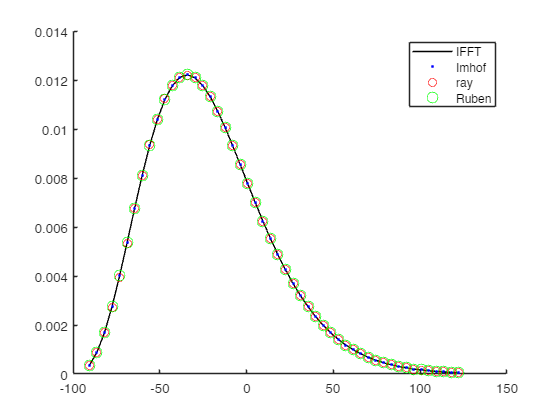

f_ruben=gx2pdf(x,w,k,lambda,s,m,'method','ruben');

figure; hold on
plot(x,f_ifft,'-k')
plot(x,f_imhof,'.b')
plot(x,f_ray,'or')
plot(x,f_ruben,'og','MarkerSize',8)
legend('IFFT','Imhof','ray', 'Ruben')

% Compute quantiles for tiny cdf values of 1e-1000 and 1e-2000, by supplying
% their log10 values. Use a forward cdf method that can get down to such tiny values.
% Here we use the ellipse approximation.
x_q=gx2inv([-1e3 -2e3],w,k,lambda,s,m,'method','ellipse')

x_q = 1.0e+03 *

   -1.2447   -1.5422



% now verify using an exact cdf method that cdf values here are indeed 1e-1000 and 1e-2000:
p=gx2cdf(x_q,w,k,lambda,s,m,'method','ellipse')

p = 1.0e+03 *

   -1.0000   -2.0000


## Compute CDF and PDF in the far tails, using some tail approximation methods too

Ray, tail and Imhof methods are best for infinite tails.

### Compute CDF in an infinite lower tail

w=[1 2 -3 -4];
k=[6 5 4 3];
lambda=[5 10 0 0];
s=10;
m=-50;

x=linspace(-500,200,40);

p_ifft=gx2cdf(x,w,k,lambda,s,m,'method','ifft','span',1e7,'n_grid',1e7);
p_imhof=gx2cdf(x,w,k,lambda,s,m,'method','imhof','abstol',0,'reltol',1e-10);

p_ray=gx2cdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e6);

Using GPU. To use only CPU, set gpu_batch to 0.


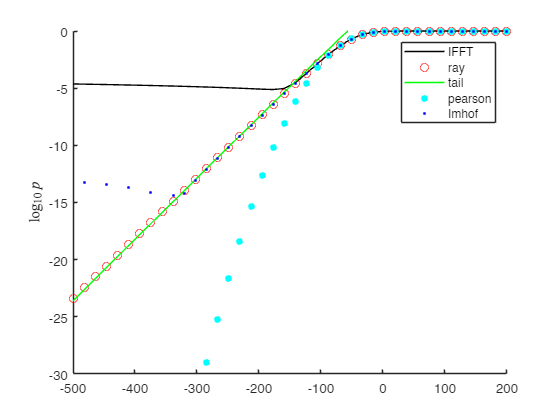

p_pearson=gx2cdf(x,w,k,lambda,s,m,'method','pearson'); % pearson sucks

% tail approximation for lower tail. Mentioning 'lower' is needed here.
% For output values that are too small for double precision, it returns
% their log10 values, which are negative.
p_tail=gx2cdf(x,w,k,lambda,s,m,'lower','method','tail');
% convert all output values to their log10
p_tail(p_tail>0)=log10(p_tail(p_tail>0));

figure; hold on
plot(x,log10(p_ifft),'-k')
plot(x,log10(p_ray),'or')
plot(x,p_tail,'-g')
plot(x,log10(p_pearson),'.c','MarkerSize',15)
plot(x,log10(p_imhof),'.b')

axis([-5e2 200 -30 0])

legend('IFFT','ray','tail', 'pearson','Imhof')
ylabel('$\log_{10} p$','Interpreter','latex')

### Compute PDF in an infinite upper tail

x=linspace(0,500,40);

f_ifft=gx2pdf(x,w,k,lambda,s,m,'method','ifft','span',1e7,'n_grid',1e7);
f_imhof=gx2pdf(x,w,k,lambda,s,m,'method','imhof','abstol',0,'reltol',1e-1);

f_ray=gx2pdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e6);

Using GPU. To use only CPU, set gpu_batch to 0.


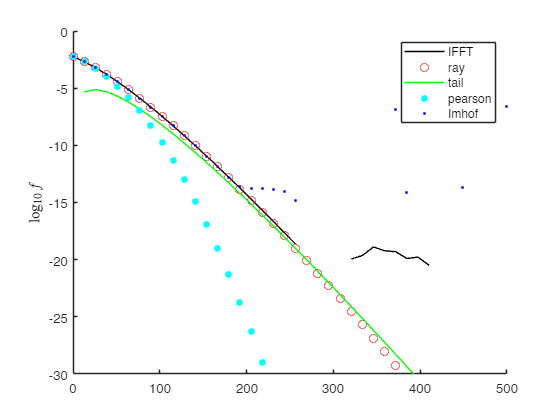

f_pearson=gx2pdf(x,w,k,lambda,s,m,'method','pearson');

% tail approximation for upper tail. Mentioning 'upper' is needed here.
f_tail=gx2pdf(x,w,k,lambda,s,m,'upper','method','tail');

figure; hold on
plot(x,log10(f_ifft),'-k')
plot(x,log10(f_ray),'or')
plot(x,log10(f_tail),'-g')
plot(x,log10(f_pearson),'.c','MarkerSize',15)
plot(x,log10(f_imhof),'.b')

axis([0 500 -30 0])

legend('IFFT','ray','tail', 'pearson','Imhof')
ylabel('$\log_{10} f$','Interpreter','latex')

### Compute CDF in a finite lower tail

Ruben and ellipse methods are best for finite tails.

w=[1 2 3 4];
k=[6 5 4 3];
lambda=[5 10 0 0];
s=0;
m=0;

x=logspace(-2,2,40);

p_ifft=gx2cdf(x,w,k,lambda,s,m,'method','ifft','span',1e7,'n_grid',1e7);
p_imhof=gx2cdf(x,w,k,lambda,s,m,'method','imhof','abstol',0,'reltol',1e-10);

p_ruben=gx2cdf(x,w,k,lambda,s,m,'method','ruben');
p_ray=gx2cdf(x,w,k,lambda,s,m,'method','ray','n_rays',1e5);

Using GPU. To use only CPU, set gpu_batch to 0.


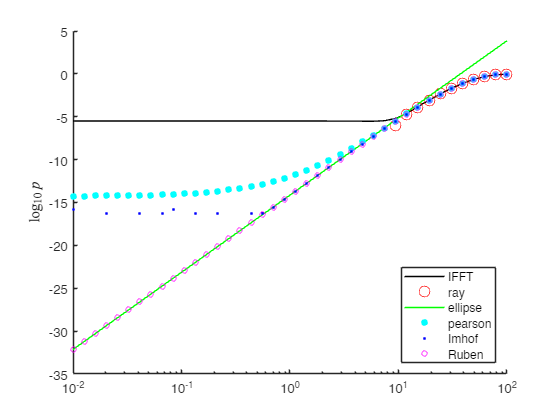

p_pearson=gx2cdf(x,w,k,lambda,s,m,'method','pearson');
p_ellipse=gx2cdf(x,w,k,lambda,s,m,'method','ellipse');

figure; hold on
plot(x,log10(p_ifft),'-k')
plot(x,log10(p_ray),'or','MarkerSize',8)
plot(x,log10(p_ellipse),'-g')
plot(x,log10(p_pearson),'.c','MarkerSize',15)
plot(x,log10(p_imhof),'.b')
plot(x,log10(p_ruben),'om','MarkerSize',4)

set(gca,'xscale','log')
legend('IFFT','ray','ellipse', 'pearson','Imhof','Ruben','Location', 'southeast')
ylabel('$\log_{10} p$','Interpreter','latex')

## Compute characteristic function

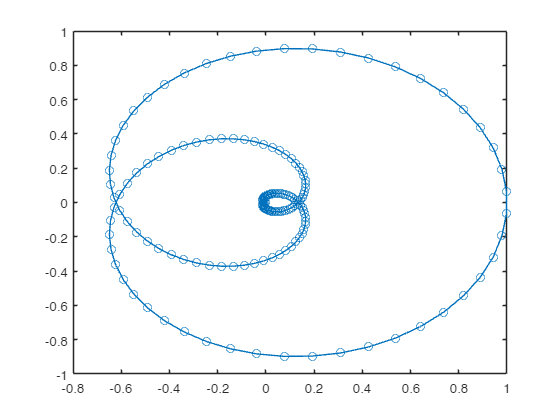

t=linspace(-1,1,1e3);
phi=gx2char(t,w,k,lambda,s,m);
figure; plot(phi,'-o')

## Distribution of quadratic form of a normal variable

Normal parameters:

mu=[5;6]; % mean
v=[2 1; 1 3]; % covariance matrix

Sample normal random vectors:

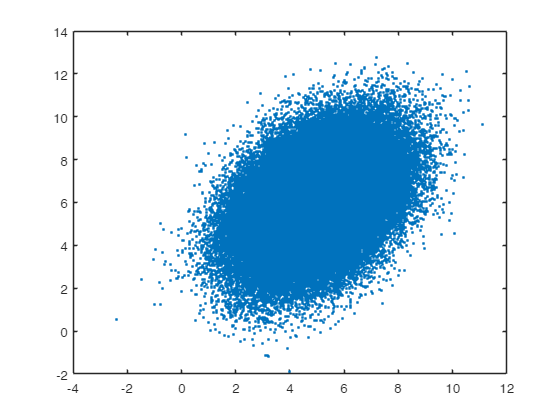

x=mvnrnd(mu,v,1e5)';
figure; plot(x(1,:),x(2,:),'.')

Quadratic form $q(\mathbf{x})=(x_1+x_2)^2-x_1-1$` = [x1;x2]'*[1 1; 1 1]*[x1;x2] + [-1;0]'*[x1;x2] -1`

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

Compute the quadratic form *q* for the sample of normal vectors:

q=dot(x,quad.q2*x)+quad.q1'*x+quad.q0;

Get generalized chi-square parameters corresponding to this quadratic form:

[w,k,lambda,s,m]=norm_quad_to_gx2_params(mu,v,quad)

w = 7.0000

k = 1

lambda = 16.6188

s = 0.8452

m = -1.3316

Compare the sampled and calculated distributions of *q*:

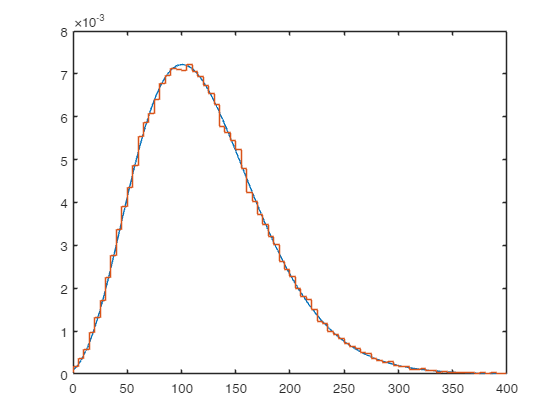

[f,~,x]=gx2pdf('full',w,k,lambda,s,m);
plot(x,f); hold on
histogram(q,'normalization','pdf','displaystyle','stairs')
xlim([0 400])

Compare the sampled and calculated means and variances:

[mu_q,v_q]=gx2stat(w,k,lambda,s,m);
[mu_q mean(q)]

ans =   122.0000  122.0403


[v_q var(q)]

ans = 1.0e+03 *

    3.3560    3.3804


Compare the sampled and calculated probabilities $p(q(\mathbf{x})<50)$:

mean(q<50)

ans = 0.0871

gx2cdf(50,w,k,lambda,s,m)

ans = 0.0856

Find a canonical quadratic form of a standard multinormal corresponding to these generalized chi-square parameters:

quad=gx2_to_norm_quad_params(w,k,lambda,s,m)

quad = struct with fields:
    q2: [2×2 double]
    q1: [2×1 double]
    q0: 115
